clc % Borra la command window
clear % Limpia las variables del workspace
format short

# Actividades

### **A.1) Mostrar las variaciones en temperatura a lo largo de los años contenidos en el archivo *****temperatureAnomalies.csv***

**Set up the Import Options and import the data**

opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Date", "Anomaly"];
opts.VariableTypes = ["datetime", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Date", "InputFormat", "yyyy-MM-dd", "DatetimeFormat", "preserveinput");

% Import the data
temperatureAnomalies = readtable("data\temperatureAnomalies.csv", opts)

temperatureAnomalies = 1644×2 table
       Date       Anomaly
    __________    _______

    1880-01-01      -0.3 
    1880-02-01     -0.21 
    1880-03-01     -0.18 
    1880-04-01     -0.27 
    1880-05-01     -0.14 
    1880-06-01     -0.29 
    1880-07-01     -0.24 
    1880-08-01     -0.08 
    1880-09-01     -0.17 
    1880-10-01     -0.16 
    1880-11-01     -0.19 
    1880-12-01     -0.22 
    1881-01-01      -0.1 
    1881-02-01     -0.14 
    1881-03-01      0.01 
    1881-04-01     -0.03 


**Clear temporary variables**

clear opts

**Visualización**

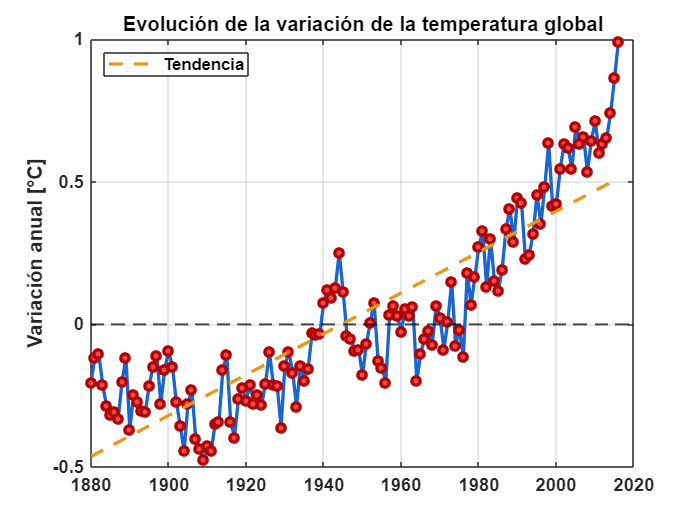

% Extraer los años y calcular la variacion media por año
years = year(temperatureAnomalies.Date);
unique_years = unique(years);
mean_anomalies = arrayfun(@(y) mean(temperatureAnomalies.Anomaly(years == y)), unique_years);

% Crear la figura
figure;
hold on;

h1 = plot(unique_years, mean_anomalies, '-o', 'Color', [0.1 0.4 0.8], 'LineWidth', 2, 'MarkerSize', 5, 'MarkerFaceColor', [0.9 0.3 0.3], 'MarkerEdgeColor', [0.7 0 0]);

% Líneas de referencia para tendencia
h2 = yline(0, '--k', 'LineWidth', 1.2, 'LabelHorizontalAlignment', 'left', 'FontSize', 10);
trend = polyfit(unique_years, mean_anomalies, 1); % Ajuste de tendencia lineal
h3 = plot(unique_years, polyval(trend, unique_years), '--', 'Color', [0.9 0.6 0.1], 'LineWidth', 2);

% Configurar etiquetas y títulos
ylabel('Variación anual [°C]', 'FontSize', 12, 'FontWeight', 'bold');
title('Evolución de la variación de la temperatura global', 'FontSize', 14, 'FontWeight', 'bold');

% Agregar detalles visuales
grid on;
box on;
set(gca, 'FontSize', 11, 'FontWeight', 'bold');

% Agregar leyenda
legend(h3, {'Tendencia'}, 'Location', 'northwest', 'FontSize', 10);

hold off;

Para esta grafica, nos aseguramos de colocar puntos individuales que sean distinguibles de la linea de la grafica. La linea azul marca un comportamiento, sin embargo, los datos reales son los puntos rojos. Para ayudar a comunicar el mensaje de la grafica, se anadio una linea de tendencia para enfatizar el incremento de la temperatura a lo largo de los anos.

### A.2) Mostrar la correlación en los datos climatológicos para la ciudad de Nueva York, contenidos en el archivo *newYork-weather.csv*

**Set up the Import Options and import the data**

opts = delimitedTextImportOptions("NumVariables", 5);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["date", "precipitation", "temp_max", "temp_min", "wind"];
opts.VariableTypes = ["datetime", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "date", "InputFormat", "dd/MM/yy", "DatetimeFormat", "preserveinput");

% Import the data
newYorkweather = readtable("data\newYork-weather.csv", opts)

newYorkweather = 1461×5 table
      date      precipitation    temp_max    temp_min    wind
    ________    _____________    ________    ________    ____

    01/01/12         1.8             10         3.3       5.1
    02/01/12           0             10         0.6       8.7
    03/01/12           0            0.6        -8.9       8.2
    04/01/12           0           -1.7       -10.6       5.5
    05/01/12           0            5.6        -3.3       5.4
    06/01/12           0           12.2           0       4.6
    07/01/12           0           16.1         2.2       4.7
    08/01/12           0            8.9         0.6       6.2
    09/01/12           0            3.9        -1.7       2.7
    10/01/12           0            8.9        -1.1       5.5
    11/01/12           3            8.3        -0.6    

**Clear temporary variables**

clear opts

**Visualización**

% Extraer solo las variables numéricas
numericData = table2array(newYorkweather(:, 2:end));

% Calcular la matriz de correlación
corrMatrix = corr(numericData, 'Rows', 'complete');

% Nombres de las variables
varNames = {'Precipitación', 'Temp Max', 'Temp Min', 'Viento'};

- **Mapa de calor de correlación**

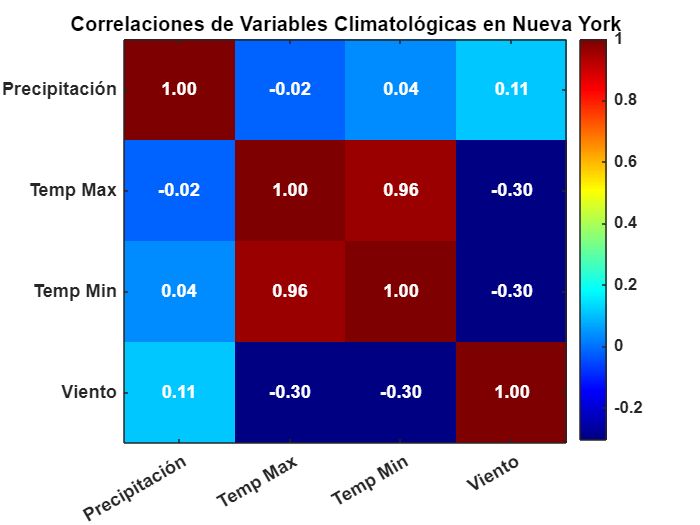

figure;
imagesc(corrMatrix); % Muestra la matriz de correlaciones
colormap(jet); % Escala de colores
colorbar; % Agregar barra de colores

% Configuración de ejes y etiquetas
xticks(1:length(varNames)); yticks(1:length(varNames));
xticklabels(varNames); yticklabels(varNames);
title('Correlaciones de Variables Climatológicas en Nueva York');
set(gca, 'FontSize', 11, 'FontWeight', 'bold');

% Mostrar valores en la matriz
textStrings = num2str(corrMatrix(:), '%.2f'); % Formato de valores
textStrings = strtrim(cellstr(textStrings)); % Convertir a celdas
[x, y] = meshgrid(1:length(varNames), 1:length(varNames));
text(x(:), y(:), textStrings, 'HorizontalAlignment', 'center', 'FontSize', 11, 'Color', 'w', 'FontWeight', 'bold');

El mapa de calor muestra con tonos mas rojizos las correlaciones positivas mas altas, y con un azul intenso las correlaciones negativas mas altas. El colorbar facilita la interpretacion de la escala de colores.

- **Matriz de dispersión**

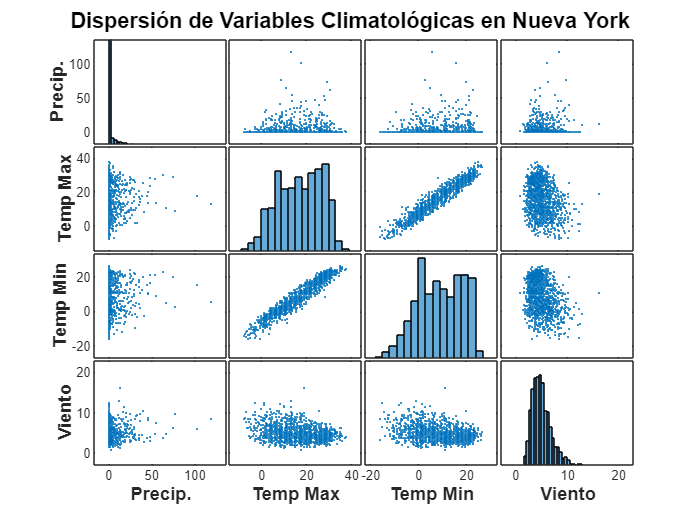

figure;
[h, ax] = plotmatrix(numericData); % h contiene los gráficos, ax los ejes

% Título general de la figura
sgtitle('Dispersión de Variables Climatológicas en Nueva York', 'FontSize', 13, 'FontWeight', 'bold');

% Nombres de las variables
varNames = {'Precip.', 'Temp Max', 'Temp Min', 'Viento'};

% Etiquetar los ejes individuales
for i = 1:length(varNames)
    ax(i, 1).YLabel.String = varNames{i}; % Etiquetas en la primera columna
    ax(i, 1).YLabel.FontSize = 11;
    ax(i, 1).YLabel.FontWeight = 'bold';
    
    ax(end, i).XLabel.String = varNames{i}; % Etiquetas en la última fila
    ax(end, i).XLabel.FontSize = 11;
    ax(end, i).XLabel.FontWeight = 'bold';
end

Esta forma de representar los datos, permite ver directamente el comportamiento de los datos, con un formato muy parecido al de seaborn en python, es facil ver que pares de variables tienen correlacion.

- **Series de tiempo**

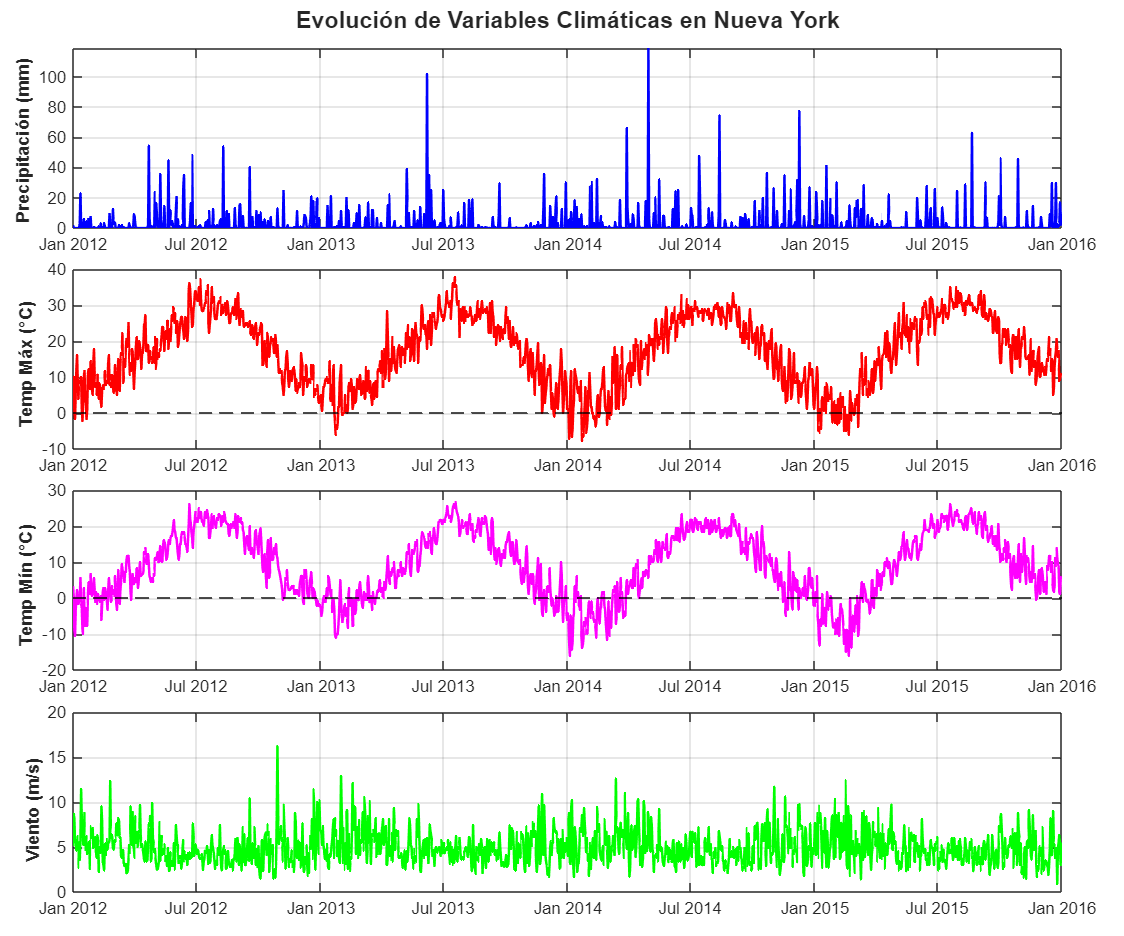

figure;
tiledlayout(4,1, 'TileSpacing', 'compact', 'Padding', 'compact');

% Variables y colores
vars = {'Precipitación (mm) ', 'Temp Máx (°C)  ', 'Temp Mín (°C)  ', 'Viento (m/s)   '}; 
colors = {'-b', '-r', '-m', '-g'};

for i = 1:4
    nexttile;
    plot(newYorkweather.date, table2array(newYorkweather(:, i+1)), colors{i}, 'LineWidth', 1.5);
    
    if i == 2 || i == 3
        yline(0, '--k', 'LineWidth', 1.2, 'LabelHorizontalAlignment', 'left', 'FontSize', 10);
    end
    % Etiqueta del eje Y
    ylabel(vars{i}, 'FontSize', 11, 'FontWeight', 'bold');

    grid on;
    set(gca, 'FontSize', 10); % Aplicar formato a cada subgráfica
end
sgtitle('Evolución de Variables Climáticas en Nueva York', 'FontSize', 14, 'FontWeight', 'bold');

% Ajustar la altura de la figura para mejorar la visualización
set(gcf, 'Position', [100, 100, 900, 750]);

En las graficas anteriores no consideramos el tipo de dato de fecha para los analisis de correlacion.Por ello, se agrego una grafica mas para poder relacionar el tiempo con las demas variables. En ella es facil ver la evolucion de las variables en el transcurso del tiempo.

### A.3) A partir de los datos de la pandemia por COVID-19 provistos en el archivo *covid.xslx*:

clc % Borra la command window
clear % Limpia las variables del workspace

- **Mostrar el total de casos positivos a COVID-19 por estado de la república**

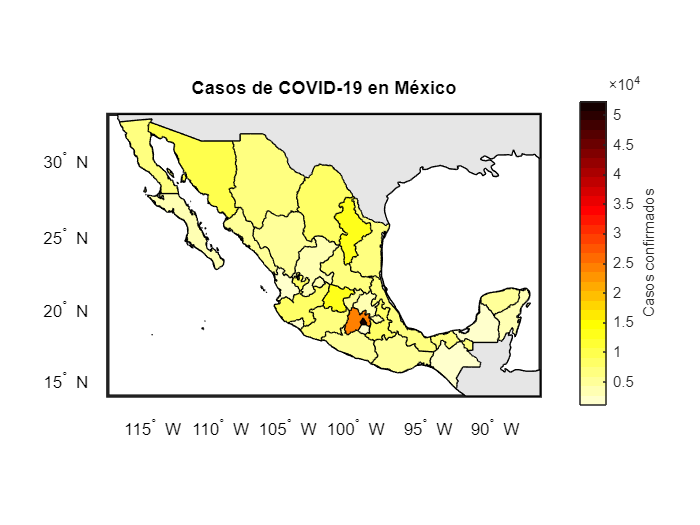

% Crear el mapa
figure;
ax = worldmap([14.0, 33.0], [-118.0, -86.0]);  % Centrar el mapa en los límites definidos
setm(ax, 'MapProjection', 'mercator');  % Usar la proyección Mercator
% Quitar el grid
gridm off;

% Mostrar el mapa base con los continentes
hold on;
geoshow('landareas.shp', 'FaceColor', [0.9 0.9 0.9]);  % Color gris claro para los continentes
title('Casos de COVID-19 en México');

% Cargar los datos de COVID-19 desde el CSV
covid_data = readtable('data/covid_clean.csv'); 

% Cargar el archivo GeoJSON con los estados de México
mexico = readgeotable('data/mexicoHigh.json');  % Cargar el archivo geoJSON

% Obtener valores de casos y definir la escala de colores
casos = covid_data.CASOS;
minCasos = min(casos);
maxCasos = max(casos);

% Normalización Min-Max
normCasos = (casos - minCasos) / (maxCasos - minCasos);  % Escalar entre 0 y 1

% Definir un colormap de colores
cmap = flipud(hot(34));
cmap = cmap(3:end, :);

% Dibujar los estados con colores según la cantidad de casos
for i = 1:32
    estado = mexico.name{i};  % Obtener el nombre del estado
    
    % Buscar el índice correspondiente en los datos de COVID-19
    idx = find(strcmpi(covid_data.ENTRESI, estado));
    
    if ~isempty(idx)  % Si se encuentra el estado en los datos
        colorIndex = round(normCasos(idx) * (size(cmap, 1) - 1)) + 1;
        faceColor = cmap(colorIndex, :);
    else
        faceColor = [0.8 0.8 0.8];  % Color gris si no hay datos
    end
    
    % Dibujar el estado con el color asignado
    geoshow(mexico(i,:), 'FaceColor', faceColor, 'EdgeColor', 'black');
end

% Agregar una barra de color
colormap(cmap);
colorbar;
clim([minCasos maxCasos]);
ylabel(colorbar, 'Casos confirmados');
hold off;

Elegimos una visualizacion de tipo mapa de calor, ya que lo importante a destacar es una valor numerico por estado mas que las ubicaciones exactas. El mapa de color va de lo mas claro (menos intenso) a lo mas rojizo oscuro (mas intenso). Estos colores representan bien los bajos y altos numeros de casos ya que asociamos el rojo con peligro y el blanco con tranquilidad. La idea es analoga para los siguientes mapas, unicamente ajustamos los datos que se ensenan en la visualizacion.

- **Mostrar el total de muertes a consecuencia del COVID-19 por estado de la república**

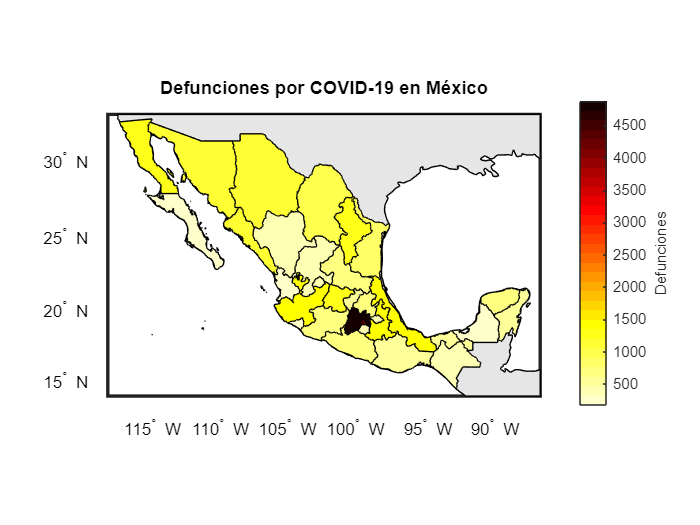

% Crear el mapa
figure;
ax = worldmap([14.0, 33.0], [-118.0, -86.0]);  % Centrar el mapa en los límites definidos
setm(ax, 'MapProjection', 'mercator');  % Usar la proyección Mercator
% Quitar el grid
gridm off;

% Mostrar el mapa base con los continentes
hold on;
geoshow('landareas.shp', 'FaceColor', [0.9 0.9 0.9]);  % Color gris claro para los continentes
title('Defunciones por COVID-19 en México');

% Obtener valores de defunciones y definir la escala de colores
deaths = covid_data.DEFUNCIONES;
minDeaths = min(deaths);
maxDeaths = max(deaths);

% Normalización Min-Max
normMuertes = (deaths - minDeaths) / (maxDeaths - minDeaths);  % Escalar entre 0 y 1

% Dibujar los estados con colores según la cantidad de muertes
for i = 1:32
    estado = mexico.name{i};  % Obtener el nombre del estado
    
    % Buscar el índice correspondiente en los datos de COVID-19
    idx = find(strcmpi(covid_data.ENTRESI, estado));
    
    if ~isempty(idx)  % Si se encuentra el estado en los datos
        colorIndex = round(normMuertes(idx) * (size(cmap, 1) - 1)) + 1;
        faceColor = cmap(colorIndex, :);
    else
        faceColor = [0.8 0.8 0.8];  % Color gris si no hay datos
    end
    
    % Dibujar el estado con el color asignado
    geoshow(mexico(i,:), 'FaceColor', faceColor, 'EdgeColor', 'black');
end

% Agregar una barra de color
colormap(cmap);
colorbar;
clim([minDeaths maxDeaths]);
ylabel(colorbar, 'Defunciones');
hold off;

- **Casos en proporción por cada 100mil habitantes**

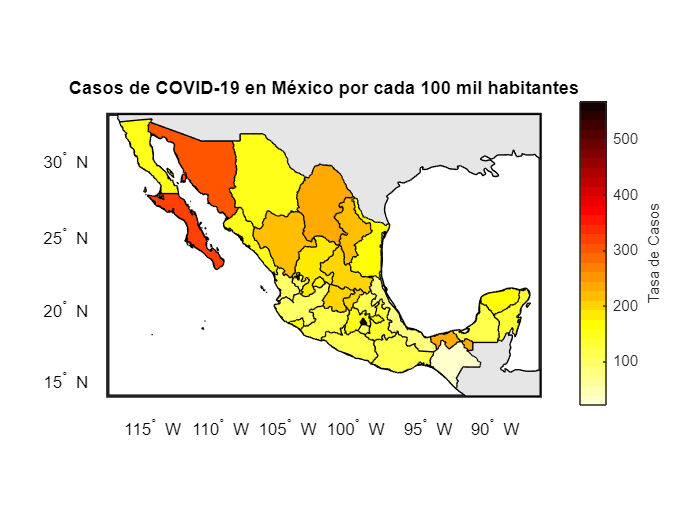

% Crear el mapa
figure;
ax = worldmap([14.0, 33.0], [-118.0, -86.0]);  % Centrar el mapa en los límites definidos
setm(ax, 'MapProjection', 'mercator');  % Usar la proyección Mercator
% Quitar el grid
gridm off;

% Mostrar el mapa base con los continentes
hold on;
geoshow('landareas.shp', 'FaceColor', [0.9 0.9 0.9]);  % Color gris claro para los continentes
title('Casos de COVID-19 en México por cada 100 mil habitantes');

% Obtener valores de casos por 100 mil hab.
pob = covid_data.POB;
casosPCMH = (casos ./ pob) * 100000;

minCasosPCMH = min(casosPCMH);
maxCasosPCMH = max(casosPCMH);

% Normalización Min-Max
normCasosPCMH = (casosPCMH - minCasosPCMH) / (maxCasosPCMH - minCasosPCMH);  % Escalar entre 0 y 1

% Dibujar los estados con colores según la cantidad de casos
for i = 1:32
    estado = mexico.name{i};  % Obtener el nombre del estado
    
    % Buscar el índice correspondiente en los datos de COVID-19
    idx = find(strcmpi(covid_data.ENTRESI, estado));
    
    if ~isempty(idx)  % Si se encuentra el estado en los datos
        colorIndex = round(normCasosPCMH(idx) * (size(cmap, 1) - 1)) + 1;
        faceColor = cmap(colorIndex, :);
    else
        faceColor = [0.8 0.8 0.8];  % Color gris si no hay datos
    end
    
    % Dibujar el estado con el color asignado
    geoshow(mexico(i,:), 'FaceColor', faceColor, 'EdgeColor', 'black');
end

% Agregar una barra de color
colormap(cmap);
colorbar;
clim([minCasosPCMH maxCasosPCMH]);
ylabel(colorbar, 'Tasa de Casos');
hold off;

- **Defunciones en proporción por cada 100mil habitantes**

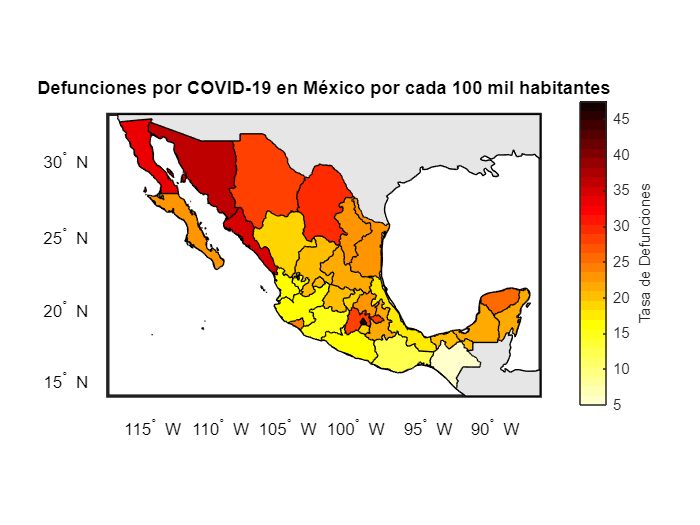

% Crear el mapa
figure;
ax = worldmap([14.0, 33.0], [-118.0, -86.0]);  % Centrar el mapa en los límites definidos
setm(ax, 'MapProjection', 'mercator');  % Usar la proyección Mercator
% Quitar el grid
gridm off;

% Mostrar el mapa base con los continentes
hold on;
geoshow('landareas.shp', 'FaceColor', [0.9 0.9 0.9]);  % Color gris claro para los continentes
title('Defunciones por COVID-19 en México por cada 100 mil habitantes');

% Obtener valores de casos por 100 mil hab.
deathsPCMH = (deaths ./ pob) * 100000;

minDeathsPCMH = min(deathsPCMH);
maxDeathsPCMH = max(deathsPCMH);

% Normalización Min-Max
normDeathsPCMH = (deathsPCMH - minDeathsPCMH) / (maxDeathsPCMH - minDeathsPCMH);  % Escalar entre 0 y 1

% Dibujar los estados con colores según la cantidad de casos
for i = 1:32
    estado = mexico.name{i};  % Obtener el nombre del estado
    
    % Buscar el índice correspondiente en los datos de COVID-19
    idx = find(strcmpi(covid_data.ENTRESI, estado));
    
    if ~isempty(idx)  % Si se encuentra el estado en los datos
        colorIndex = round(normDeathsPCMH(idx) * (size(cmap, 1) - 1)) + 1;
        faceColor = cmap(colorIndex, :);
    else
        faceColor = [0.8 0.8 0.8];  % Color gris si no hay datos
    end
    
    % Dibujar el estado con el color asignado
    geoshow(mexico(i,:), 'FaceColor', faceColor, 'EdgeColor', 'black');
end

% Agregar una barra de color
colormap(cmap);
colorbar;
clim([minDeathsPCMH maxDeathsPCMH]);
ylabel(colorbar, 'Tasa de Defunciones');
hold off;

### A.4) La curvatura está dada por la siguiente ecuación

## 
$$\kappa =\frac{|x\prime y\prime \prime -y\prime x\prime \prime |}{{\left({\left(x\prime \right)}^2 +{\left(y\prime \right)}^2 \right)}^{\frac{3}{2}} }$$


### A partir de los datos que representan una curva por sus posiciones (*x,y*) en el plano, contenidos en el archivo *curve_tab.txt*, realizar una visualización de la curvatura

clc % Borra la command window
clear % Limpia las variables del workspace
addpath('lib');

** Import data**

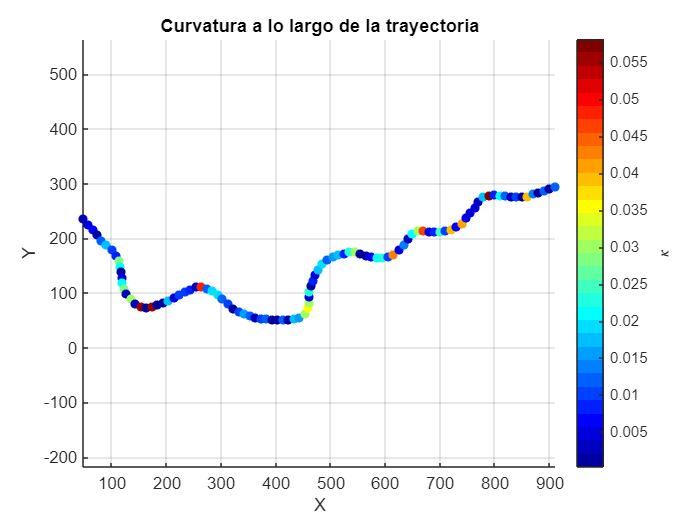

% Cargar datos
data = readmatrix('data/curve_tab.txt');

% Separar coordenadas X e Y
X = data(:,1);
Y = data(:,2);

X_fit = X(1:10:end);
Y_fit = Y(1:10:end);

% Calcular las derivadas usando la función SplineDerivativeT
[dxdt, dydt, dxxdt2, dyydt2] = SplineDerivativeT(X_fit, Y_fit);
% Calcular la curvatura
kappa = abs(dxdt .* dyydt2 - dydt .* dxxdt2) ./ ((dxdt.^2 + dydt.^2).^(3/2));

scatter(X_fit, Y_fit, 30, kappa, 'filled');
colormap jet;
colorbar; % Agrega barra de color para interpretar los valores de curvatura
ylabel(colorbar, '$\kappa$', 'Interpreter','latex');
grid on; % Activa la cuadrícula
xlabel('X');
ylabel('Y');
title('Curvatura a lo largo de la trayectoria');
axis equal;

Para evitar el problema de la discretizacion, se hizo un filtrado de los datos originales. Tomamos uno de cada 10 puntos para evaluar las curvaturas. Podemos ver como, a traves de la trayectoria, en curvas mas pronunciadas se presentan valores mas altod e curvatura y en partes mas planas tenemos valores mas bajos de curvatura.

### **A.5) **Usando  el  software  Slicer  3D  y  a  partir  del  volumen  `CT_Pulmones.mhd`  el cual contiene los datos de una tomografía computada (CT) de los pulmones de un paciente con  COVID-19  hacer  una  visualización  tridimensional  que  delimite  la  superficie  de  los pulmones y que además muestre las afectaciones por COVID-19 dentro de los pulmones

Para obtener la visualizacion se siguieron los siguientes pasos:

**1. Crear tres segmentos nuevos: **

- **Pulmones**

- **Bronquios**

- **Lesiones pulmonares** (asignarles el color rojo para diferenciarlos).

**2. Generar el modelo 3D de los pulmones**

- Usar la herramienta de threshold para seleccionar la región adecuada.

- Hacer clic en "Aplicar".

- Seleccionar el segmento correcto y utilizar la herramienta de "Island" para aislar la estructura deseada.

- Aplicar suavizado con un valor de 5 mm para reducir pequeñas irregularidades.

- Realizar otro suavizado con una configuración de 3 mm para mejorar la apariencia del modelo.

**3. Crear el segmento de los bronquios**

- Cambiar la opacidad de la segmentación para visualizar mejor la estructura.

- Usar la herramienta de "Flood filling" en una región estable, asegurándose de no borrar otras asignaciones.

- Ajustar el parámetro de tolerancia de identidad a 15.

- Aplicar la herramienta de enmascarado y rellenar con un valor de 4 mm para completar pequeños espacios.

**4. Segmentación de las lesiones pulmonares**

- Ocultar las visualizaciones de los pulmones y bronquios para enfocarse en las lesiones.

- Usar la herramienta de "Threshold" para seleccionar regiones con la densidad adecuada, tratando de aislar las lesiones sin incluir tejido circundante.

- Proceder manualmente: 

- Utilizar la herramienta de pincel para pintar las áreas correspondientes a las lesiones pulmonares.

- Repetir este proceso para todas las regiones afectadas.

**5. Mejorar la visualización de las lesiones**

- Aplicar la herramienta de suavizado en la segmentación de las lesiones.

- Desactivar el "Editable intensity range" y trabajar en modo "Overlap".

- Aplicar la opción de "Filling" con un valor inicial de 3 mm para mejorar la segmentación.

- Realizar un último suavizado para mejorar la apariencia.

**7. Finalización**

- Visualizar el modelo 3D con las tres estructuras segmentadas.

**Resultado obtenido:**